# Unsaturetad Flow in a Porous media - Richard's model (Under Construction)

cd(strcat(gres_root,'/Tutorial/0X_richards'))
richards_root = fullfile(gres_root,'Tests','Richards','Case2');

This is a tutorial decribing how to use the unsaturated flow in a porous media using Richards modulo currently available in GReS. 

## Governing equations

Mass conservation of slightly compressible unsaturated fluid is given by


$$\sigma(S) \frac{\partial p}{\partial t} + \nabla \cdot \bigg( \lambda(S) \mathbf{K} \nabla ( p + \gamma z)\bigg)= q,$$
   

where:

- $\sigma$ is the store coefficient;

- $\lambda$ is the fluid mobility;

- $\mathbf{K}$ is the permeability tensor;

- $ \gamma$ is the specifiy weight of the fluid;

- $q$ is the external volumetric flux;

- $p$ is the pressure field;

- $z$ is the heigth;

- $S$ is the saturation.

The following boundary conditions can be prescribed


$$\begin{cases}
    p(\mathbf{x},t) = p_D(\mathbf{x},t) 
    & \text{on } \,  \Gamma_p:\ \text{prescribed pressure} \\[6pt]

    \mathbf{q}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = q_N(\mathbf{x},t) 
    & \text{on } \, \Gamma_q:\ \text{prescribed flux}
\end{cases}
$$


In this model, the primary variable is the pressure field and the variables $\sigma$ and $\lambda$ are dependent on the saturation level. The store coefficient coded in GReS is expressed as


$$\sigma(S) = S\bigg(\alpha+\beta\phi\bigg) + \phi\frac{dS}{dp}$$


where: 

- $\alpha$ - rock compressibility;

- $\beta$ - fluid compressibility;

- $\phi$ - porosity;

and the fluid mobility is given by


$$\lambda(S) = \frac{k_{r}(S)}{\mu}$$


- $k_{r}(S)$ is relative permeability of the fluid;

- $\mu$ is the dynamic viscosity of the fluid.

## Problem setting

This numerical experiment reproduces the study described by Varella, 2018. It simulates the one-dimensional, incompressible version of Richards' equation. The domain is a 100 cm-long column of initially dry soil. A higher pressure head is imposed at the top boundary, which causes a water infiltration front to develop and move downward over time.

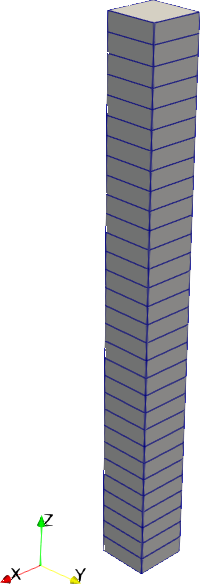

## Model setup

The first step is defining the active physical models in the simulation, creating an instance of the class `ModelType.`

### Setting the physics

The first step is defining the active physical models in the simulation, creating an instance of the class `ModelType.`

For the Richards problem, we need a VariabSatFlow model, for this the discretization scheme adopt is necessary to be the two-point-flux-approximation Finite Volume scheme for the pressure. This is created in the experiment by the command

model = ModelType("VariabSatFlow_FVTPFA");

### Setting the non-linear solver behaivor

We then specify the parameters of the simulation creating an object of the class` SimulationParameters, `which requires a .dat file as input.

fileName = fullfile(richards_root,'Inputs','simParam.dat');
simParam = SimulationParameters(fileName,model)

simParam =   SimulationParameters with properties:

            itMaxNR: 20
             relTol: 1.0000e-08
             absTol: 1.0000e-09
              pNorm: 2
              theta: 1
              dtIni: 10
              dtMin: 10
              dtMax: 1000
               tIni: 0
               tMax: 259200
            multFac: 1.1000
             divFac: 2
           relaxFac: 0
            pTarget: 1.0000e+11
            sTarget: 0.4000
           NLSolver: 'Newton'
          verbosity: 2
       goOnBackstep: 0
    isTimeDependent: 1

  Show all accessible properties of SimulationParameters


### Material

It`s created based in the experiment provied 

fileName = strcat(input_dir,'simParam.dat');
simParam = SimulationParameters(fileName,model);

In GReS, the variables $S$ and $k_{r}$ are expressed depend on pressure in two different ways: through tabulated data or via the van Genuchten model Genuchten, 1980, Genuchten, 1985, MRST, 2019. In both cases, the saturation is described in terms as effective saturation, following


$$S_{e} = \frac{S-S_{r}}{S_{s}-S_{r}}$$


with:

- $S$ is the saturation;

- $S_{e}$ is the effective saturation;

- $S_{r}$ is the residual saturation;

- $S_{s}$ is the maximum saturation for the fluid.

#### Tabular Data Format

In this case, the variables $S_{e}$ and $k_{r}$ are store in a table that contains the information about the variable and it's correspondent pressure (see fig:Tabular Curves). 

Tabular Curves: Example of tabular curves for the effective saturation and the relative permeability.

The material is defined in the material class, and you need to provieded a file with the proprieties defined. In the code, 

% Set the input file name and path
fileName = fullfile(richards_root,'Inputs','materialsList.dat');

% Create an object of the Materials class and read the materials file
mat = Materials(model,fileName);

#### Van Genuchten Model

The relationship between capillary pressure and water saturation is


$$S_{e} = \bigg(1+(\epsilon p)^{n}\bigg)^{-m}$$


- $\epsilon$ is related to the average size of pores

- $n$ and $m$ are experimental parameters.

The relative permeability be given by the van Genuchten–Mualem model,


$$k_{r} = S_{e}^{k}\bigg[1-\bigg(1 - S_{e}^{1/m}\bigg)^{m}\bigg]^{2},    \quad m=1-1/n$$


where $k$ is a connectivity factor, usually 0.5. Or by the van Genuchten-Burdine model,


$$k_{r} = S_{e}^{2}\bigg[1-\bigg(1 - S_{e}^{1/m}\bigg)^{m}\bigg],    \quad m=1-2/n$$


### Domain

It`s created based in the experiment provied 

## References

*M. Th. van Genuchten. A Closed-form Equation for Predicting the Hydraulic Conductivity of Unsaturated Soils. In: Soil Science Society of America Journal 44.5 (1980), pp. 892–898. doi: *[*https://doi.org/10.2136/sssaj1980.03615995004400050002x*](https://doi.org/10.2136/sssaj1980.03615995004400050002x)

*Martinus Van Genuchten and D.R. Nielsen. On Describing and Predicting the Hydraulic Properties of Unsaturated Soils. In: Annales Geophysicae 3 (Jan. 1985), pp. 615–628.*

*Knut-Andreas Lie. An Introduction to Reservoir Simulation Using MATLAB/GNU Octave: User Guide for the MATLAB Reservoir Simulation Toolbox (MRST). Cambridge University Press, 2019*

*Varela, Jhabriel. Implementation of an MPFA/MPSA-FV solver for the unsaturated flow in deformable porous media. 2018.*